## DSP 7600: Assignment 2

## Prepaired by Andrew Stone (201534971)

## Prepaired for Dr. Sarah Power

### **Section 1 | **

#### 1.1 | 

  i)  $x\left\lbrack n\right\rbrack =\left\lbrace \begin{array}{ll}
\left\lbrace \begin{array}{ll}
3 & n=0\\
2 & n=1
\end{array}\right. & \\
\left\lbrace \begin{array}{ll}
1 & n=2\\
0 & \textrm{else}
\end{array}\right. & 
\end{array}\right.$    ii) $x\left\lbrack n\right\rbrack =\left\lbrace \begin{array}{ll}
1 & 0\le n\le 6\\
0 & \textrm{else}
\end{array}\right.$

#### **1.a  | DFT**

Compute N-Point DFT via transform equation for n ∈ N  = { 32, 64, 128, 256 }


$$X\left\lbrack k\right\rbrack =\sum_{n=0}^{N-1} x\left\lbrack n\right\rbrack e^{-j\omega_o n} \;=\;\sum_{n=0}^{N-1} x\left\lbrack n\right\rbrack e^{-j\frac{2\pi \;}{N}\textrm{kn}} \;,\;k=0,1,2,\ldotp \ldotp \ldotp ,\;N-1$$


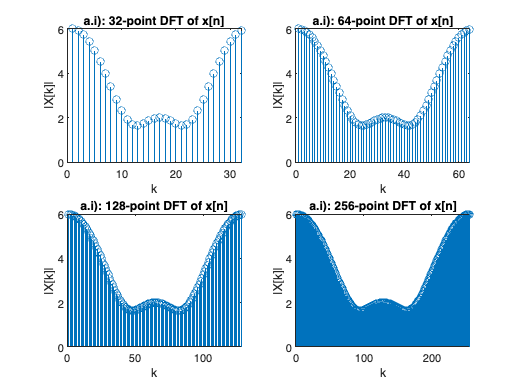

% i)
xi = [3 2 1];
Xk_32 = DFT(xi, 32);
Xk_64 = DFT(xi, 64);
Xk_128 = DFT(xi, 128);
Xk_256 = DFT(xi, 256);

% figure1 = figure("Name", "N-point DFT", "Color", "black");
figure1 = figure("Name", "N-point DFT");

List = { Xk_32, Xk_64, Xk_128, Xk_256 };
ListName = [ "32-point", "64-point", "128-point", "256-point" ];

for i = 1 : length(List)
    subplot(2,2, i);
    stem(abs( cell2mat(List(i)) ));
    xlabel('k');
    xlim( [0 length( cell2mat(List(i)) )] );
    ylabel('|X[k]|');
    title( sprintf("a.i): %s DFT of x[n]", ListName(i)) );
end

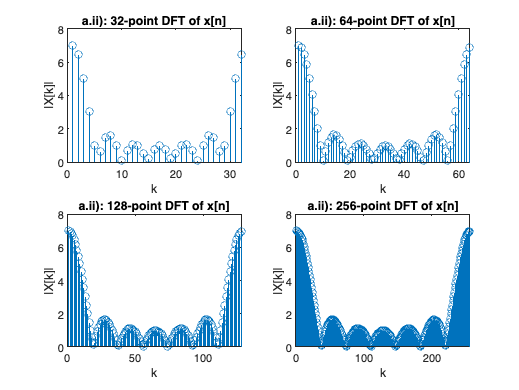


% ii)
xii = [1 1 1 1 1 1 1];
Xk_32 = DFT(xii, 32);
Xk_64 = DFT(xii, 64);
Xk_128 = DFT(xii, 128);
Xk_256 = DFT(xii, 256);

figure2 = figure("Name","N-point DFT");

List = { Xk_32, Xk_64, Xk_128, Xk_256 };
ListName = [ "32-point", "64-point", "128-point", "256-point" ];

for i = 1 : length(List)
    subplot(2,2, i);
    stem(abs( cell2mat(List(i)) ));
    xlabel('k');
    xlim( [0 length( cell2mat(List(i)) )] );
    ylabel('|X[k]|');
    title( sprintf("a.ii): %s DFT of x[n]", ListName(i)) );
end

#### 1.b | DTFT


$$x_i \left\lbrack n\right\rbrack =\left\lbrace \begin{array}{ll}
\left\lbrace \begin{array}{ll}
3 & n=0\\
2 & n=1
\end{array}\right. & \\
\left\lbrace \begin{array}{ll}
1 & n=2\\
0 & \textrm{else}
\end{array}\right. & 
\end{array}\right.$$



$$\begin{array}{l}
X_i \left(e^{j\omega \;} \right)=\;\sum_{n=-\infty }^{\infty } x\left\lbrack n\right\rbrack e^{-j\omega n} =\sum_{n=0}^2 x\left\lbrack n\right\rbrack e^{-j\omega n} =\sum 3e^0 +2e^{-j\;\omega } +e^{-j\;2\omega } \\
=3+2e^{-j\;\omega } +e^{-j\;2\omega } 
\end{array}$$



$$X_i \left(e^{j\omega \;} \right)\;\textrm{evaluated}\;\textrm{at}\;\omega =\frac{2\pi }{32}\;\textrm{and}\;\omega =\frac{9\pi }{8}\ldotp \ldotp \ldotp \;$$


    $X_i \;\left(\;e^{j\;\frac{2\pi }{32}\;} \;\right)=5\ldotp 9360$ ;   $X_{\textrm{ii}} \;\left(\;e^{j\;\frac{9\pi }{8}\;} \;\right)=1\ldotp 8603$

Corrisponding *k* value for various N such that $X\left\lbrack n\right\rbrack =5\ldotp 9360$

        
$$N=32\to k=\frac{2\pi \;}{32}\div \frac{2\pi \;}{32}=1\to X_i \left\lbrack 1\right\rbrack =5\ldotp 9360$$


        
$$N=64\to k=\frac{2\pi \;}{32}\div \frac{2\pi \;}{64}=2\to X_i \left\lbrack 2\right\rbrack =5\ldotp 9360$$


        
$$N=128\to k=\frac{2\pi \;}{32}\div \frac{2\pi \;}{128}=4\to X_i \left\lbrack 4\right\rbrack =5\ldotp 9360$$


        
$$N=256\to k=\frac{2\pi \;}{32}\div \frac{2\pi \;}{256}=8\to X_i \left\lbrack 8\right\rbrack =5\ldotp 9360$$


Corrisponding *k* value for various N such that $X\left\lbrack n\right\rbrack =1\ldotp 8603$

        
$$N=32\to k=\frac{9\pi \;}{8}\div \frac{2\pi \;}{32}=18\to X_i \left\lbrack 18\right\rbrack =1\ldotp 8603$$


        
$$N=64\to k=\frac{9\pi \;}{8}\div \frac{2\pi \;}{64}=36\to X_i \left\lbrack 36\right\rbrack =1\ldotp 8603$$


        
$$N=128\to k=\frac{9\pi \;}{8}\div \frac{2\pi \;}{128}=72\to X_i \left\lbrack 72\right\rbrack =1\ldotp 8603$$


        
$$N=256\to k=\frac{9\pi \;}{8}\div \frac{2\pi \;}{256}=144\to X_i \left\lbrack 144\right\rbrack =1\ldotp 8603$$



$$x_{\textrm{ii}} \left\lbrack n\right\rbrack =\left\lbrace \begin{array}{ll}
1 & 0\le n\le 6\\
0 & \textrm{else}
\end{array}\right.$$



$$\begin{array}{l}
X_{\textrm{ii}} \left(e^{j\omega \;} \right)=\;\sum_{n=-\infty }^{\infty } x\left\lbrack n\right\rbrack e^{-j\omega n} =\sum_{n=0}^6 x\left\lbrack n\right\rbrack e^{-j\omega n} =\sum {\left(1\right)e}^0 +{\left(1\right)e}^{-j\;\omega } +\;{\left(1\right)e}^{-j\;2\omega } +{\left(1\right)e}^{-j\;3\omega } +{\left(1\right)e}^{-j\;4\omega } +{\left(1\right)e}^{-j\;5\omega } +{\left(1\right)e}^{-j\;6\omega } \\
=1+e^{-j\;\omega } +\;e^{-j\;2\omega } +e^{-j\;3\omega } +e^{-j\;4\omega } +e^{-j\;5\omega } +e^{-j\;6\omega } 
\end{array}$$



$$X_{\textrm{ii}} \left(e^{j\omega \;} \right)\;\textrm{evaluated}\;\textrm{at}\;\omega =\frac{2\pi }{32}\;\textrm{and}\;\omega =\frac{9\pi }{8}\ldotp \ldotp \ldotp \;$$


    $X_{\textrm{ii}} \left(\;e^{j\;\frac{2\pi }{32}\;} \;\right)=6\ldotp 4723$ ;   $X_{\textrm{ii}} \left(\;e^{j\;\frac{9\pi }{8}\;} \;\right)=0\ldotp 1989$

Corrisponding *k* value for various N such that $X\left\lbrack n\right\rbrack =6\ldotp 4723$

        
$$N=32\to k=\frac{2\pi \;}{32}\div \frac{2\pi \;}{32}=1\to X_{\textrm{ii}} \left\lbrack 1\right\rbrack =6\ldotp 4723$$


        
$$N=64\to k=\frac{2\pi \;}{32}\div \frac{2\pi \;}{64}=2\to X_{\textrm{ii}} \left\lbrack 2\right\rbrack =6\ldotp 4723$$


        
$$N=128\to k=\frac{2\pi \;}{32}\div \frac{2\pi \;}{128}=4\to X_{\textrm{ii}} \left\lbrack 4\right\rbrack =6\ldotp 4723$$


        
$$N=256\to k=\frac{2\pi \;}{32}\div \frac{2\pi \;}{256}=8\to X_{\textrm{ii}} \left\lbrack 8\right\rbrack =6\ldotp 4723$$


Corrisponding *k* value for various N such that $X\left\lbrack n\right\rbrack =0\ldotp 1989$

        
$$N=32\to k=\frac{9\pi \;}{8}\div \frac{2\pi \;}{32}=18\to X_{\textrm{ii}} \left\lbrack 18\right\rbrack =0\ldotp 1989$$


        
$$N=64\to k=\frac{9\pi \;}{8}\div \frac{2\pi \;}{64}=36\to X_{\textrm{ii}} \left\lbrack 36\right\rbrack =0\ldotp 1989$$


        
$$N=128\to k=\frac{9\pi \;}{8}\div \frac{2\pi \;}{128}=72\to X_{\textrm{ii}} \left\lbrack 72\right\rbrack =0\ldotp 1989$$


        
$$N=256\to k=\frac{9\pi \;}{8}\div \frac{2\pi \;}{256}=144\to X_{\textrm{ii}} \left\lbrack 144\right\rbrack =0\ldotp 1989$$


Comments:

- Magnitude of DFT are the same for all *k* corrisponding to $\omega$.

- This is a result of the evaluation of $\frac{2\pi }{N}$ which dictates the "distance" between subsequent frequency values.

- Because $\frac{2\pi }{32}$ and $\frac{9\pi }{8}$ is an integer multiple of $\frac{2\pi }{N}$, there exists integer solutions to $\omega =k\;\frac{2\pi }{N}$.

function out = DFT(x_, N_)
    x = [x_ zeros(1, (N_-length(x_)))]; % padd input array x_ to match length of N_
    out = zeros(1, N_);
    for k = 0 : N_-1
        for n = 0 : N_-1
            out(k+1) = out(k+1) + x(n+1) * exp(1j * 2 * pi() / N_ * k * n);
        end
    end
end
